# 3-Dimensional Plotting

## 3-Dimensional plots are used to obtain surfaces where z is function of two variables:

                                
$$z=f\left(x,y\right)$$


## 1. Using Mesh function

The mesh function covers the outline of the data points using value-dependent colors.

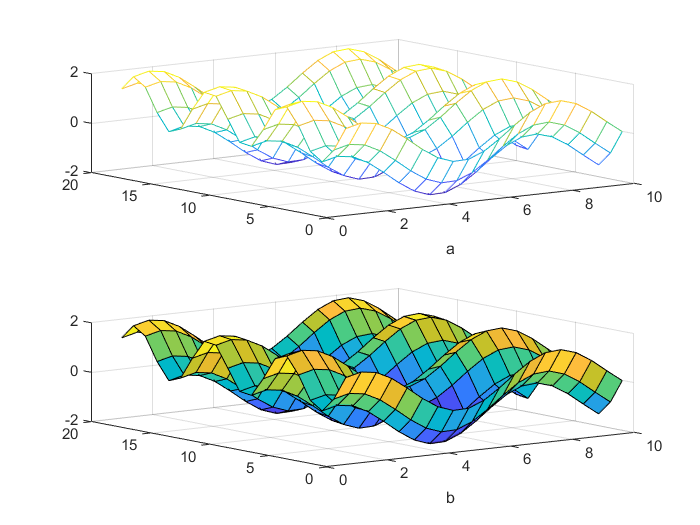

[X, Y] = meshgrid(1:0.5:10, 1:20);
x =sin(X);
y = cos(Y);
Z = sin(X)+ cos(Y);

subplot(2,1,1);
mesh(X,Y,Z)
xlabel('a')

subplot(2,1,2);
mesh(X, Y, Z)
xlabel('b')

## 2. Using Surf function

The surf function fills the inside of the graph using value-dependent colors.

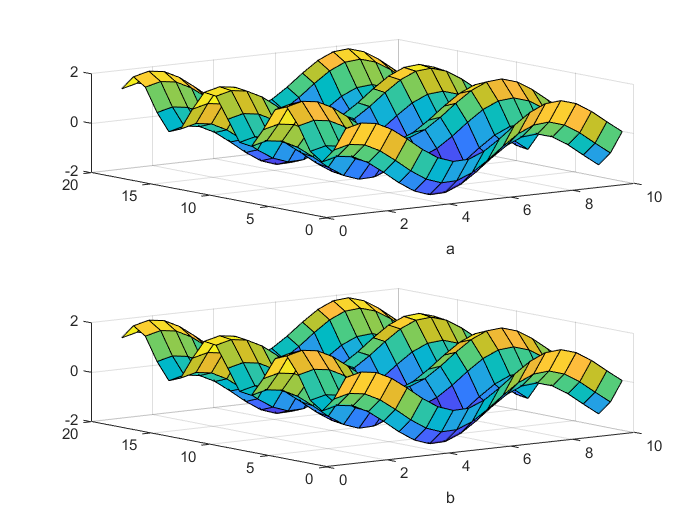

[X, Y] = meshgrid(1:0.5:10, 1:20);
Z = sin(X)+ cos(Y);

subplot(2,1,1);
surf(X,Y,Z)
xlabel('a')

subplot(2,1,2);
surf(X, Y, Z)
xlabel('b')

## Orientation Changing + Shape: Cylinder 

`Cylinder(r)` returns a 3D Matrix containing the datapoints. 

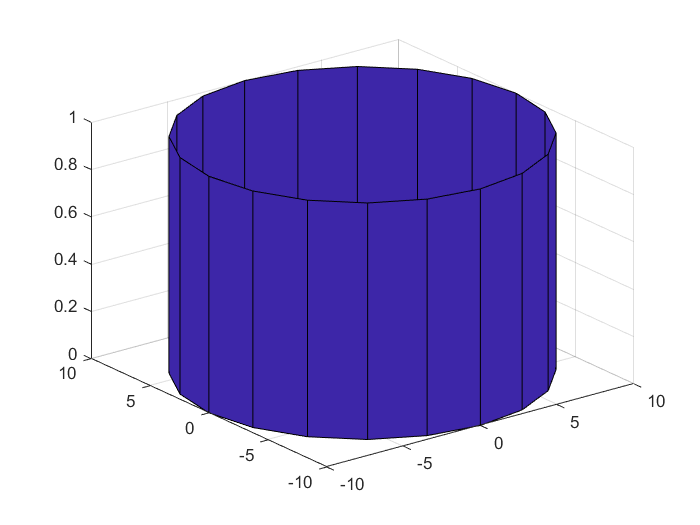

r = input('Enter the radius');
[x, y, z] = cylinder(r);
surf(x,y,z);

## Linspace + Modifying the axes of a graph

**Linspace (X1, X2, N=100)** generates a linearly spaced vector.

The function **axes( [Xmin Xmax Ymin Ymax] )** is used to modify the limits of the axes of the graph.

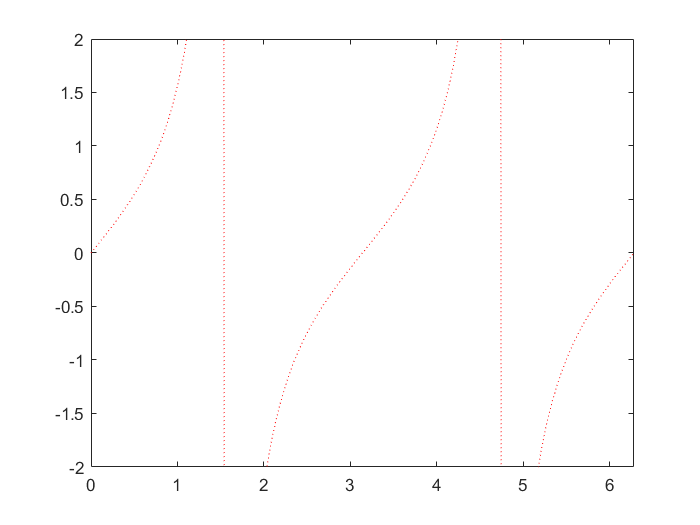

x = linspace(0, 2*pi, 100);
y = tan(x);
plot(x,y,'r:')
axis([0 2*pi -2 2])

## Generate random data points and then calculate the mean of the data.

**rand(M, N) **generates a matrix of M x N pseudorandom numbers.

n= 500;
r =rand(n,1);
plot(r)

m = mean(r)

m = 0.4942

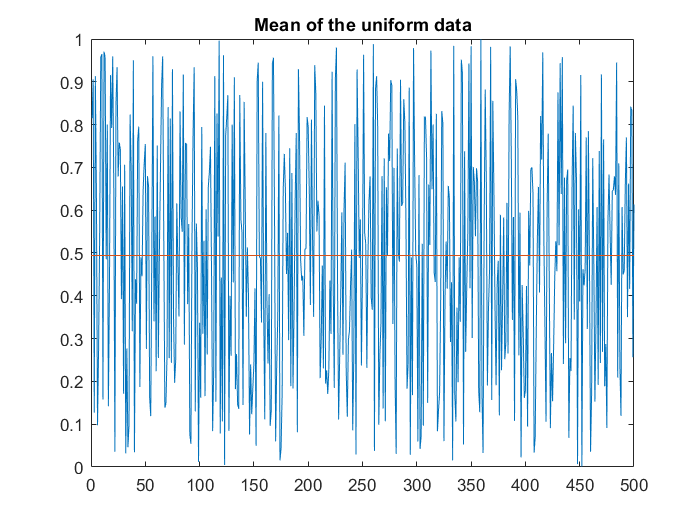

hold on
plot([0,n],[m,m])
hold off
title('Mean of the uniform data')